clear;

sGes = load(".\sGes.mat");

hGes = load(".\hGes.mat");

t=[-3, 0, 5]; f_borders=[4, 30]; t_ref = [-2.5, -0.5];

addpath(".\ERDS-Maps")

% map1 = calcErdsMap(sGes.sGes, hGes.hGes, t, f_borders,'class', 1,'ref',t_ref,'sig','boot','alpha',0.01,'montage',[1 1 1]);
% map2 = calcErdsMap(sGes.sGes, hGes.hGes, t, f_borders,'class', 2,'ref',t_ref,'sig','boot','alpha',0.01,'montage',[1 1 1]);
% 
% plotErdsMap(map1)
% plotErdsMap(map2)

onset = hGes.hGes.TRIG;
fs = 512;
function window_interest = extract_windows(onset, data)
    fs = 512;
    window_size = fs * 2;
    window_interest = zeros(length(onset), window_size, 3);

    for i=1:length(onset)
        start_idx = onset(i);
        end_idx = start_idx + window_size -1;
        window_interest(i, :, :) = data(start_idx+fs:end_idx+fs, :);
    end
end

window_interest = extract_windows(onset, sGes.sGes);
size(window_interest);

labels = hGes.hGes.Classlabel;
labels = labels == 1;

hand = window_interest(labels, :, :);
feet = window_interest(~labels, :, :);

lowCutoff = 10; % Low cutoff frequency
highCutoff = 13; % High cutoff frequency
[b, a] = butter(4, [lowCutoff, highCutoff] / (fs / 2), 'bandpass');

% Apply the bandpass filter to the data
%filteredHand = filtfilt(b, a, hand);
%filteredFeet = filtfilt(b, a, feet);
%filteredreference = filtfilt(b, a, window_reference);

function x = processData(x, b, a)
    x = permute(x, [2 1 3]); %time x N x channels
    x = filtfilt(b, a, x);
    % square
    x = x .^ 2;
    % sum
    x = sum(x, 1);
    % log
    x = log(x + 1e-10);
    % remove complex part
    x = real(x);
    x = permute(x, [2 1 3]);
end
   
filteredHand = processData(hand, b, a);

x = x(:,:,1) =

   1.0e+36 *

    0.0772    0.1399    0.0064    0.0423    0.0029    0.0004    0.0126    0.0001    0.0460    0.0033    0.0085    0.0378    0.0018    0.0017    0.0614    0.0424    0.0092    0.0002    0.0281    0.0072    0.0290    0.0795    0.0042    0.0014    0.0081    0.0746    0.0232    0.0049    0.0032    0.0637    0.0846    0.1352    0.0456    0.0179    0.0982    0.2727    0.0022    0.0021    0.0072    0.0006    0.0002    0.0761    0.0231    0.0103    0.0054    0.0154    0.0607    0.0392    0.0174    0.0537
    0.2022    0.0770    0.0000    0.0643    0.0070    0.0006    0.0185    0.0001    0.0477    0.0318    0.0129    0.0745    0.0016    0.0000    0.0338    0.0535    0.0378    0.0001    0.0088    0.0191    0.0314    0.1154    0.0002    0.0011    0.0089    0.0948    0.0338    0.0076    0.0072    0.0695    0.1167    0.1372    0.0378    0.0342    0.0738    0.3775    0.0000    0.0147    0.0135    0.0001    0.0087    0.0731    0.0129    0.0059    0.0067    0.0469    0.082

x = x(:,:,1) =

   1.0e+38 *

    1.5305    1.3828    0.5262    1.2809    0.7128    0.5110    0.5113    0.7378    0.2520    0.9354    1.9935    0.4356    0.6800    0.3924    0.8239    0.5208    0.5913    0.5845    0.5528    0.5145    0.4387    0.6368    0.9511    0.5348    0.1313    0.3532    0.3443    0.5884    0.4174    0.5432    0.5334    1.9017    0.4636    0.6899    0.5501    2.8779    0.6723    0.9314    0.5101    0.8884    1.1313    1.1128    0.3726    0.3002    0.4811    0.7745    0.6386    0.5778    0.7512    0.6351


x(:,:,2) =

   1.0e+38 *

    0.6074    0.1677    0.7409    0.2467    0.1715    0.2170    1.3321    0.8665    0.3490    0.7246    1.1251    0.5384    1.0385    1.7656    0.9202    0.7484    1.3735    0.8546    0.8365    0.9952    0.9235    0.4398    0.7980    0.6229    0.1840    1.0103    1.2750    0.5163    0.9329    0.4733    1.0299    0.4547    1.1815    0.5082    0.8406    2.7874    1.1706    1.5675    1.6813    1.5127    0.5604    0.7100    0.6902    0.7786 

x = x(:,:,1) =

   87.9238   87.8224   86.8563   87.7458   87.1597   86.8268   86.8275   87.1942   86.1199   87.4314   88.1881   86.6672   87.1126   86.5628   87.3045   86.8459   86.9728   86.9613   86.9054   86.8337   86.6744   87.0469   87.4480   86.8723   85.4683   86.4577   86.4319   86.9679   86.6246   86.8879   86.8697   88.1410   86.7295   87.1271   86.9006   88.5553   87.1011   87.4272   86.8252   87.3799   87.6216   87.6051   86.5109   86.2951   86.7665   87.2427   87.0497   86.9497   87.2121   87.0443


x(:,:,2) =

   86.9997   85.7128   87.1983   86.0987   85.7350   85.9705   87.7850   87.3549   86.4455   87.1761   87.6161   86.8791   87.5360   88.0667   87.4151   87.2085   87.8156   87.3411   87.3197   87.4935   87.4187   86.6767   87.2726   87.0249   85.8056   87.5085   87.7412   86.8372   87.4288   86.7503   87.5277   86.7101   87.6650   86.8213   87.3246   88.5233   87.6558   87.9477   88.0178   87.9121   86.9191   87.1558   87.1274   87.2480   87.8993   87.8608   86.293

filteredFeet = processData(feet, b, a);

x = x(:,:,1) =

   1.0e+36 *

    0.0000    0.0357    0.1367    0.0362    0.0024    0.0087    0.0141    0.0095    0.0052    0.2321    0.0000    0.0001    0.0064    0.1912    0.0223    0.0077    0.7907    0.2078    0.1541    0.0061    0.0176    0.0427    0.0406    0.0002    0.3816    0.1727    0.0188    0.0004    0.4677    0.1636    0.1545    0.0343    0.1851    0.0437    0.5303    0.1838    0.0033    0.0424    0.0449    0.0131    0.0009    0.0345    0.0666    0.0640    0.1200    0.1790    0.0028    0.1234    0.0020    0.0891
    0.0034    0.0569    0.0943    0.0376    0.0043    0.0061    0.0235    0.0007    0.0204    0.3312    0.0092    0.0544    0.0018    0.2041    0.0632    0.0578    0.8171    0.3420    0.2706    0.0030    0.0323    0.0391    0.0317    0.0000    0.2673    0.1705    0.0028    0.0205    0.6918    0.2075    0.1327    0.0274    0.1607    0.0263    0.6270    0.2249    0.0076    0.0999    0.0691    0.0097    0.0012    0.0195    0.0815    0.0568    0.2408    0.2272    0.021

x = x(:,:,1) =

   1.0e+38 *

    2.2874    2.9747    1.4235    4.2089    0.6744    0.5462    1.0079    4.0503    2.5387    2.1297    3.5952    6.1244    2.0801    2.1074    3.3113    2.2419    4.2997    2.9025    2.6792    1.6664    1.2444    1.3013    1.9332    1.5100    2.5506    1.5419    2.6432    1.7377    3.7610    3.7238    4.3923    1.8050    3.5451    1.4468    4.6846    4.3414    2.6302    3.2049    2.9184    4.4052    0.5311    1.2880    0.6347    0.4411    3.9314    2.1012    1.3069    1.7406    0.9309    3.1835


x(:,:,2) =

   1.0e+38 *

    0.5365    1.9294    0.8842    0.6259    1.2092    0.8492    1.6910    1.2878    1.9900    2.1365    1.3841    1.6288    1.9560    2.1441    0.6428    1.4215    0.8707    1.0078    0.9797    1.6105    2.2032    0.3882    1.4707    1.2391    1.0128    3.2905    3.8216    1.2564    2.1979    0.5439    2.9060    0.8616    1.6881    0.2681    5.8430    1.5467    2.5519    1.2092    1.2008    0.6824    1.2421    0.8682    1.5925    2.5144 

x = x(:,:,1) =

   88.3257   88.5884   87.8513   88.9354   87.1044   86.8934   87.5061   88.8970   88.4299   88.2542   88.7778   89.3105   88.2306   88.2437   88.6956   88.3055   88.9568   88.5638   88.4838   88.0089   87.7168   87.7616   88.1574   87.9104   88.4346   87.9312   88.4702   88.0508   88.8229   88.8130   88.9781   88.0888   88.7638   87.8676   89.0425   88.9664   88.4653   88.6629   88.5693   88.9810   86.8655   87.7514   87.0437   86.6797   88.8672   88.2407   87.7659   88.0525   87.4266   88.6562


x(:,:,2) =

   86.8756   88.1554   87.3752   87.0297   87.6882   87.3348   88.0235   87.7511   88.1864   88.2574   87.8233   87.9861   88.1691   88.2610   87.0563   87.8500   87.3598   87.5060   87.4777   87.9748   88.2881   86.5520   87.8840   87.7126   87.5110   88.6893   88.8389   87.7265   88.2858   86.8892   88.5650   87.3493   88.0218   86.1817   89.2635   87.9344   88.4351   87.6882   87.6812   87.1161   87.7150   87.3569   87.9635   88.4203   89.2214   88.5238   87.352


Y_hand = -1*ones(1, size(filteredHand,1));
Y_feet = ones(1, size(filteredFeet,1));

% concatenate data for hand and feet together to make training data
X_train = cat(1, filteredHand, filteredFeet);
Y_train = cat(1, Y_hand, Y_feet);

% for training, we consider only the first channel

X_train = X_train(:, :, 1);
% X_train(:)
% Y_train(:)
lda_model = fitcdiscr(X_train, Y_train(:));

prediction = predict(lda_model, X_train(:));
% Evaluate the prediction results
accuracy = sum(prediction == Y_train(:)) / length(Y_train(:));
disp(['Accuracy train data: ', num2str(accuracy)]);

Accuracy train data: 0.52


sGes_test = load(".\sGes_test.mat");

hGes_test = load(".\hGes_test.mat");

Accuracy test data: 0.98333


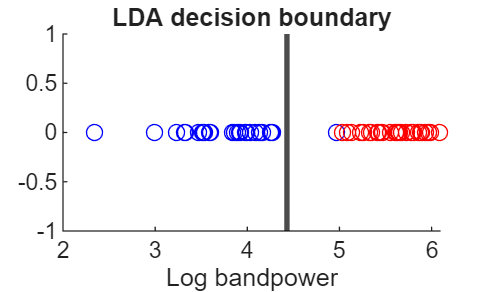

% Prepare test data for prediction
window_test_interest = extract_windows(hGes_test.hGes_test.TRIG, sGes_test.sGes_test);
filteredTest = processData(window_test_interest, b, a);
filteredTest = filteredTest(:, :, 1);
prediction_test = predict(lda_model, filteredTest(:));

labels = hGes_test.hGes_test.Classlabel;
labels = labels == 1; %hand is where it is true
n_hand = sum(labels);
% labels are originally 1 and 2, but we turn them into 1 and -1
labels = (double(labels) * -2) + 1;

accuracy_test = sum(prediction_test == labels(:)) / length(labels(:));

disp(['Accuracy test data: ', num2str(accuracy_test)]);

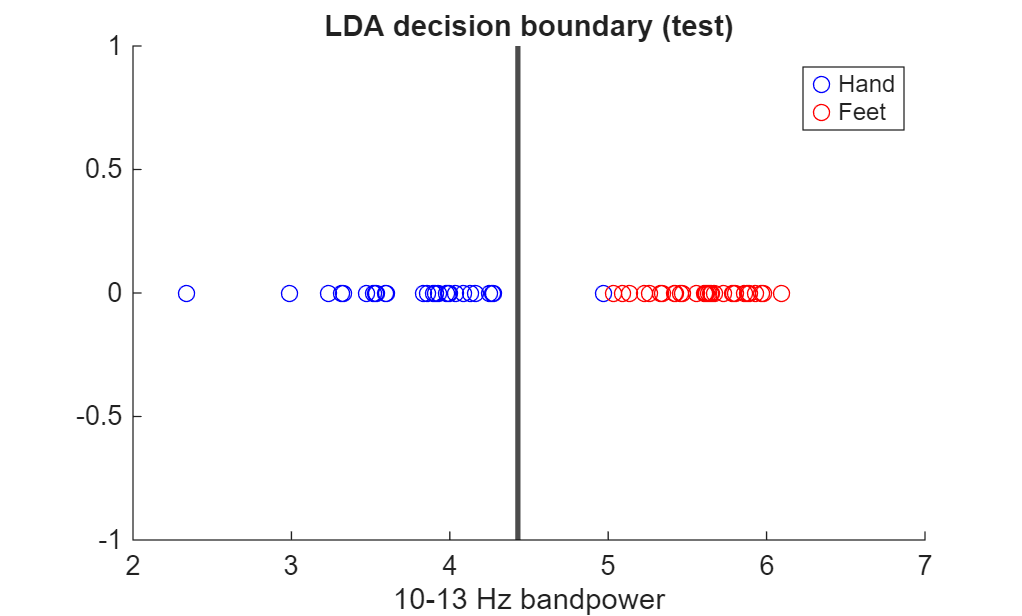

x_range = linspace(min(filteredTest), max(filteredTest), 500)';
[label, score] = predict(lda_model, x_range);

boundary_idx = find(diff(label));
decision_boundary = x_range(boundary_idx);

%Test
figure
hold on

scatter(filteredTest(labels==-1), zeros(sum(labels==-1),1), 'bo')
scatter(filteredTest(labels==1),  zeros(sum(labels==1),1), 'ro')

xline(decision_boundary, 'k', 'LineWidth',2)

xlabel('10-13 Hz bandpower')
title('LDA decision boundary (test)')
legend('Hand','Feet')

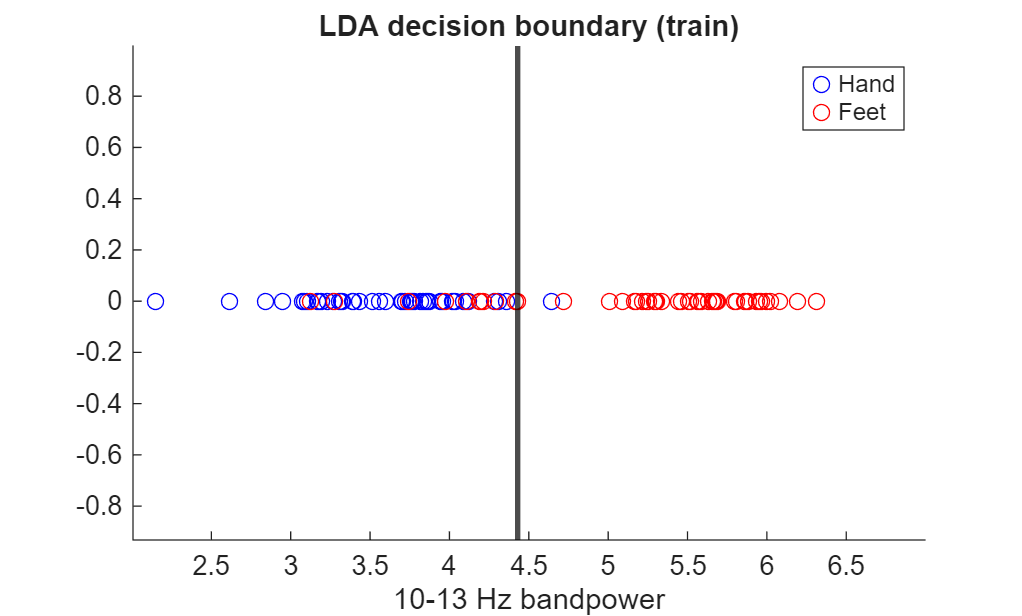


%Train
figure
hold on

labels_plot = [Y_train(1, :), Y_train(2, :)]';

scatter(X_train(labels_plot(:)==-1), zeros(sum(labels_plot==-1),1), 'bo')
scatter(X_train(labels_plot(:)==1),  zeros(sum(labels_plot==1),1), 'ro')

xline(decision_boundary, 'k', 'LineWidth',2)

xlabel('10-13 Hz bandpower')
title('LDA decision boundary (train)')
legend('Hand','Feet')

% 20-25 band for second feature 
lowCutoff = 20; % Low cutoff frequency
highCutoff = 25; % High cutoff frequency
[b_2, a_2] = butter(4, [lowCutoff, highCutoff] / (fs / 2), 'bandpass');
filteredHand2 = processData(hand, b_2, a_2);
filteredFeet2 = processData(feet, b_2, a_2);
% Prepare the training data for the second feature
X_train_2 = cat(1, filteredHand2, filteredFeet2);
% select first channel
X_train_2 = X_train_2(:, :, 1);
% we add the concatenate the two features together
X_train_2 = cat(2, X_train(:), X_train_2(:));

lda_model_2 = fitcdiscr(X_train_2, Y_train(:));
prediction_2 = predict(lda_model_2, X_train_2);

accuracy = sum(prediction_2 == Y_train(:)) / length(Y_train(:));
disp(['Accuracy train data with 2 features: ', num2str(accuracy)]);

Accuracy train data with 2 features: 0.52



filteredTest2 = processData(window_test_interest, b_2, a_2);
filteredTest2 = filteredTest2(:, :, 1);
% concatenate the two features
filteredTest2 = cat(2, filteredTest, filteredTest2);
prediction_2_test = predict(lda_model_2, filteredTest2);
accuracy_test = sum(prediction_2_test == labels(:)) / length(labels(:));
disp(['Accuracy test data with 2 features: ', num2str(accuracy_test)]);

Accuracy test data with 2 features: 0.58333


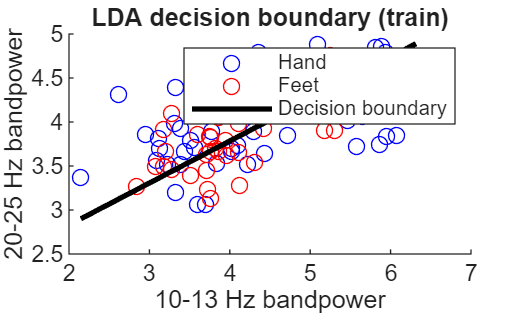

%Train
figure
hold on

scatter(X_train_2(Y_train==-1,1), X_train_2(Y_train==-1,2), 'bo')
scatter(X_train_2(Y_train==1,1),  X_train_2(Y_train==1,2),  'ro')

xlabel('10-13 Hz bandpower')
ylabel('20-25 Hz bandpower')
title('LDA decision boundary (train)')
legend('Hand','Feet')

% compute decision boundary
w = lda_model_2.Coeffs(1,2).Linear;
b = lda_model_2.Coeffs(1,2).Const;

x_vals = linspace(min(X_train_2(:,1)), max(X_train_2(:,1)), 200);
y_vals = -(w(1)*x_vals + b) / w(2);

plot(x_vals, y_vals, 'k', 'LineWidth',2, 'DisplayName','Decision boundary')

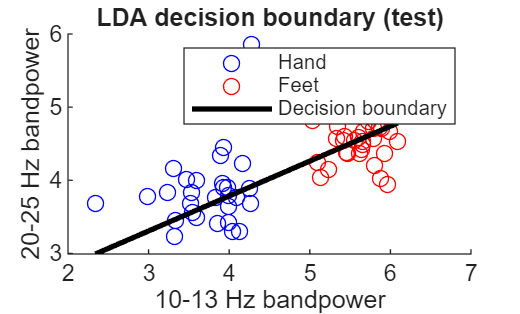


figure
hold on

scatter(filteredTest2(labels==-1,1), filteredTest2(labels==-1,2), 'bo')
scatter(filteredTest2(labels==1,1),  filteredTest2(labels==1,2),  'ro')

xlabel('10-13 Hz bandpower')
ylabel('20-25 Hz bandpower')
title('LDA decision boundary (test)')
legend('Hand','Feet')

x_vals = linspace(min(filteredTest2(:,1)), max(filteredTest2(:,1)), 200);
y_vals = -(w(1)*x_vals + b) / w(2);

plot(x_vals, y_vals, 'k', 'LineWidth',2, 'DisplayName','Decision boundary')